A = [0 1;-2 -3];
b= [0 1;1 0];
B = [0 1;1 0];
C = [1 0];
D = [0 0];
sys = ss(A, B, C, D)

sys =
 
  A = 
       x1  x2
   x1   0   1
   x2  -2  -3
 
  B = 
       u1  u2
   x1   0   1
   x2   1   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



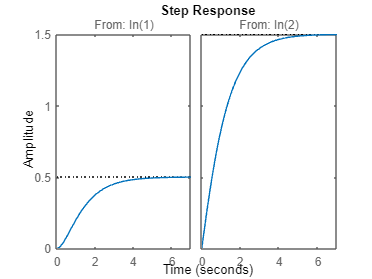


step(sys)

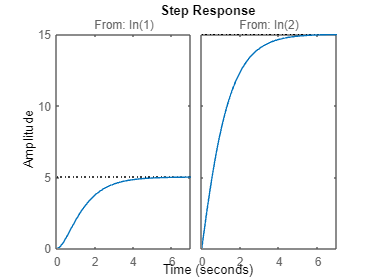

step(10*sys)

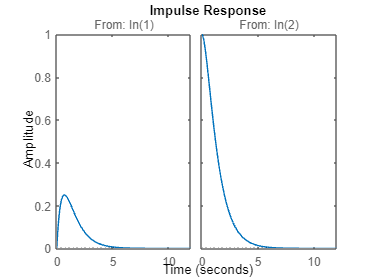

impulse(sys)

eig(A)

ans =     -1
    -2



syms s;

G = C*inv(s*eye(2) - 2) * B + D

$$G = \left(\begin{array}{cc} -\frac{2}{4\,s-s^{2}} & -\frac{s-2}{4\,s-s^{2}} \end{array}\right)$$


[n, d] = ss2tf(A, B, C, D, 1)

n =      0     0     1


d =      1     3     2



[n, d] = ss2tf(A, B, C, D, 2)

n =      0     1     3


d =      1     3     2


[a, b, c, d] = tf2ss(8, [1 6 10])